# Estimating Transfer Function Models for a Heat Exchanger

The measured data is stored in an excel file [heat_exchanger.xlsx](https://amc.smilelab.dev/content/notes/05-time_series_modelling_and_analysis/heat_exchanger.xlsx) and includes measurements of changes in coolant temperature around a nominal and changes in product temperature around a nominal. Estimate a transfer function for the heat exchanger.

dat = readtable("heat_exchanger.xlsx");

head(dat)

     Time     CoolantTemperature    ProductTemperature
    ______    __________________    __________________

         0            1                         0     
    0.0017            1                  0.009301     
    0.0034            1                  0.014269     
    0.0051            1                  0.014811     
    0.0068            1                  0.017559     
    0.0085            1                  0.011928     
    0.0102            1                  0.025423     
    0.0119            1                  0.025793     



t = dat.Time(:);                 % minutes
u = dat.CoolantTemperature(:);   % input (coolant temp change)
y = dat.ProductTemperature(:);   % output (product temp change)

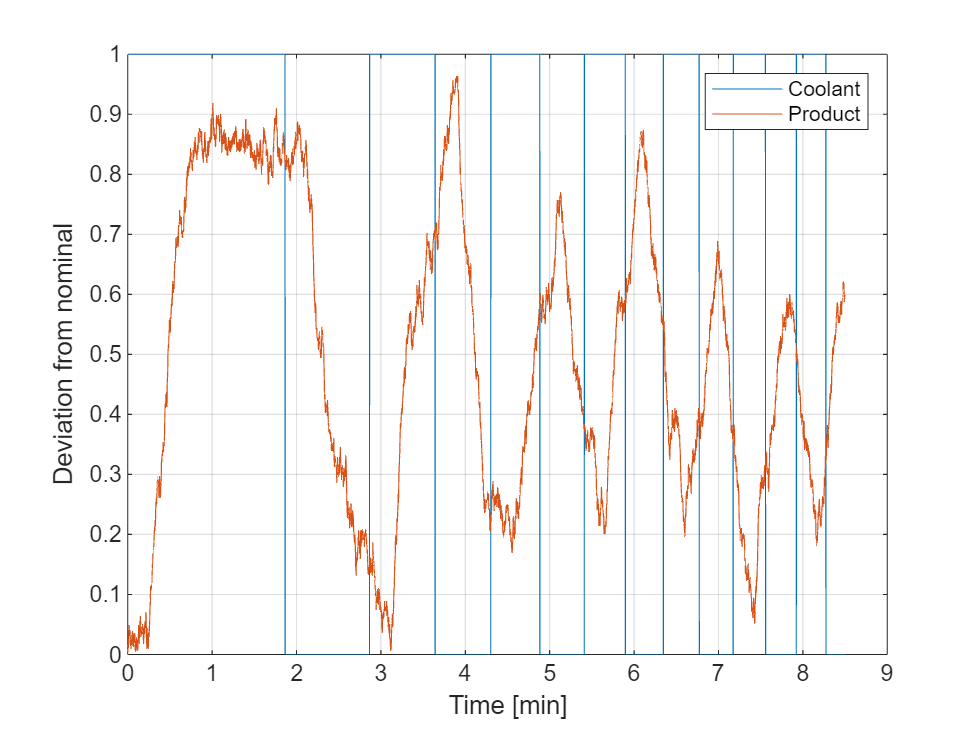

figure
plot(t,u,'-','DisplayName','Coolant'), hold on
plot(t,y,'-','DisplayName','Product')
xlabel('Time [min]'), ylabel('Deviation from nominal')
legend, grid on

% Sample time --> simple
Ts  = dat.Time(2) - dat.Time(1);  

data = iddata(y,u,Ts,'TimeUnit','min')

data =

Time domain data set with 5000 samples.
Sample time: 0.0017 minutes             
                                        
Outputs      Unit (if specified)        
   y1                                   
                                        
Inputs       Unit (if specified)        
   u1                                   
                                        
Data Properties



sysTF = tfest(data,1,0,nan)

sysTF =
 
  From input "u1" to output "y1":
                    1.438
  exp(-0.0493*s) * --------
                   s + 1.53
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 0
   Number of free coefficients: 2
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 36%                      
FPE: 0.02625, MSE: 0.02622                       
 
Model Properties



% fit FOPDT
% nd = max(0, round(delayest(dat)));      % delay in samples
% m  = tfest(dat, 1, 0, nd);              % np=1, nz=0, ioDelay=nd*Ts

%% Report the FOPDT parameters
K     = dcgain(sysTF);                      % process gain
tau   = 1/abs(pole(sysTF));                 % time constant [s]
theta = sysTF.IODelay;                      % input–output delay [s]
fprintf('Estimated FOPDT:  G(s) = %g * exp(-%g s) / ( %g s + 1 )\n', K, theta, tau);

Estimated FOPDT:  G(s) = 0.940198 * exp(-0.0493 s) / ( 0.65368 s + 1 )


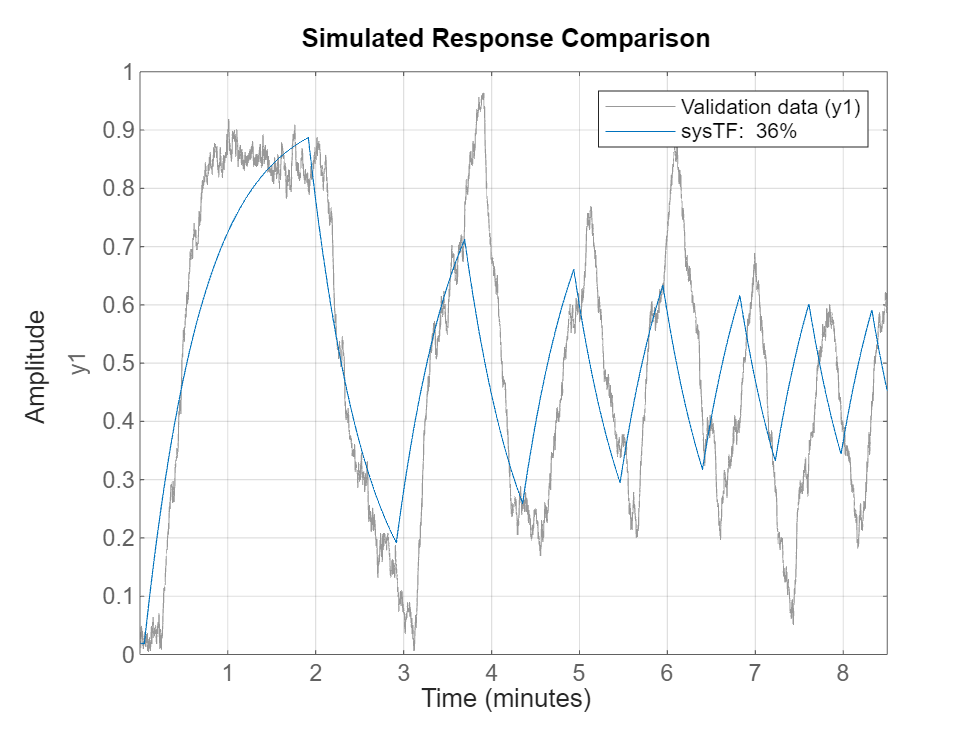

%% Fit quality
figure
compare(data, sysTF), grid on

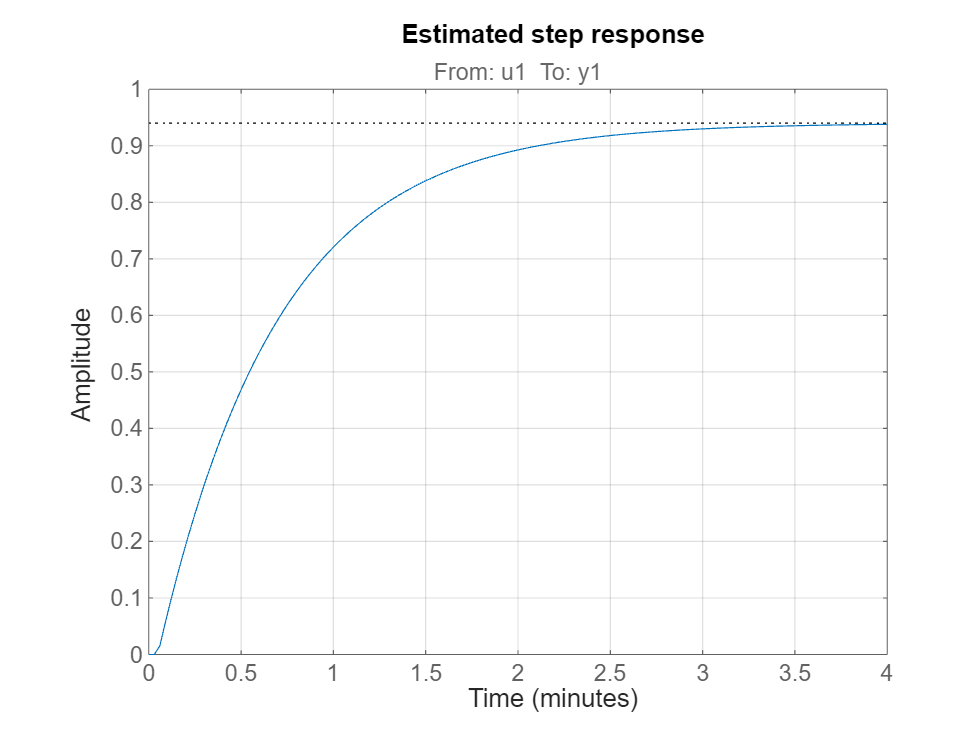

%% Step and residual analysis
figure, step(sysTF), grid on, title('Estimated step response')

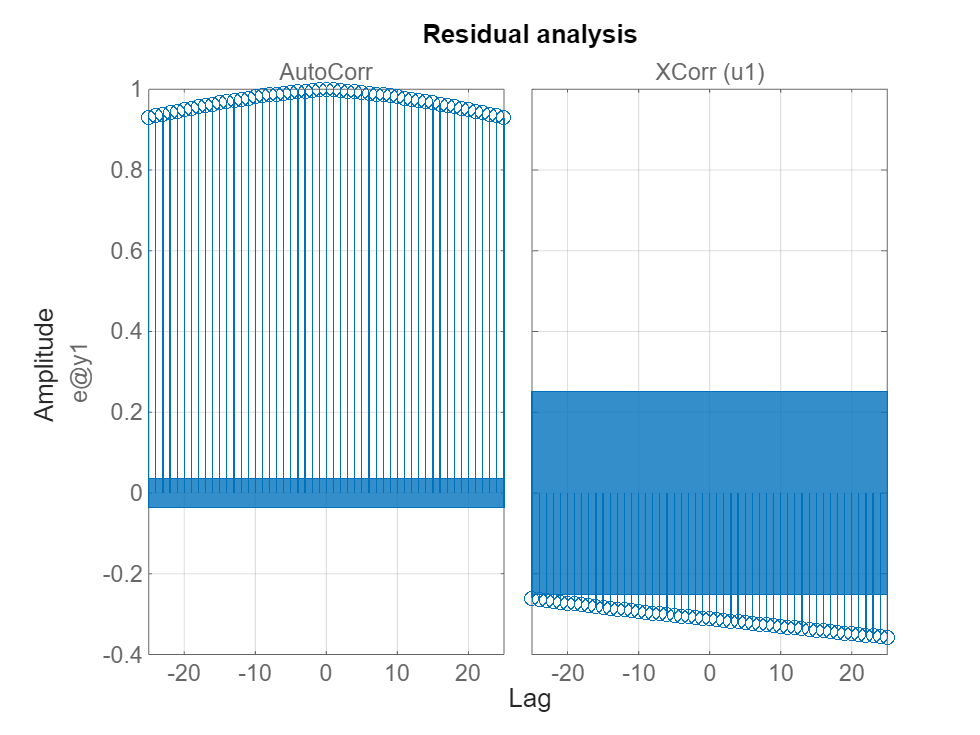

figure, resid(data, sysTF), grid on, title('Residual analysis')

### **Transfer Function Estimation from an Initial System**

sysInit = idtf(NaN,[1 NaN],'ioDelay',NaN);
sysInit.TimeUnit = 'minutes';

sysInit.Structure.num.Value   = 1;
sysInit.Structure.num.Minimum = 0;
sysInit.Structure.den.Value   = [1 1];
sysInit.Structure.den.Minimum = [0 0];

sysInit.Structure.ioDelay.Value   = 0.2;
sysInit.Structure.ioDelay.Minimum = 0;
sysInit.Structure.ioDelay.Maximum = 1;

sysTF_initialized = tfest(data,sysInit)

sysTF_initialized =
 
  From input "u1" to output "y1":
                    1.935
  exp(-0.151*s) * ---------
                  s + 2.085
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 0
   Number of free coefficients: 2
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 54.42%                   
FPE: 0.01331, MSE: 0.0133                        
 
Model Properties


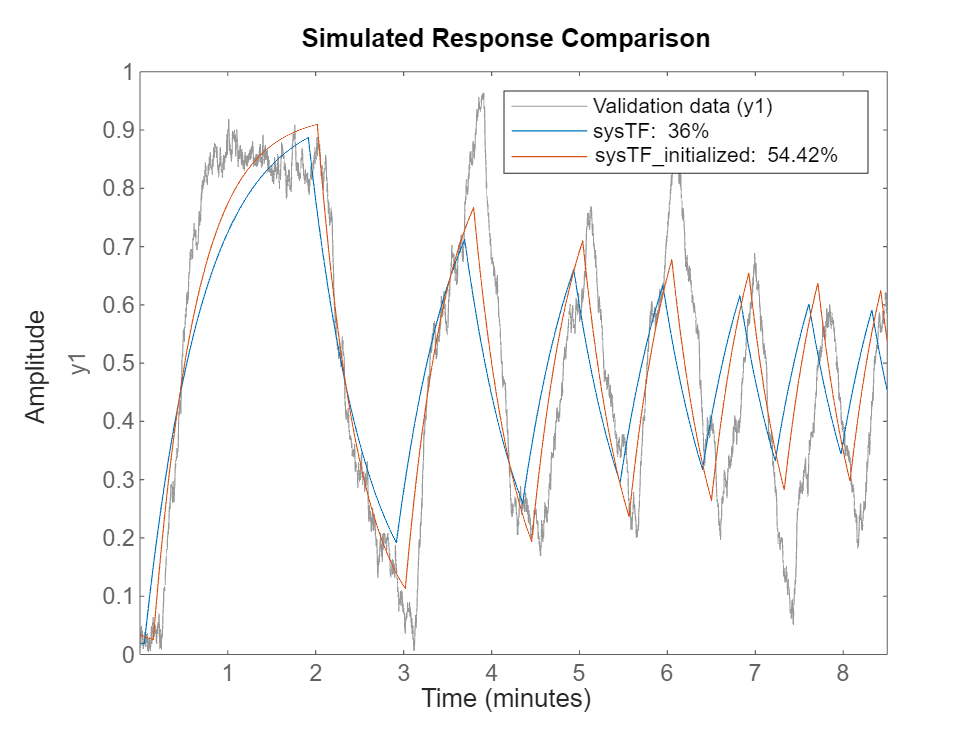


compare(data,sysTF,sysTF_initialized)

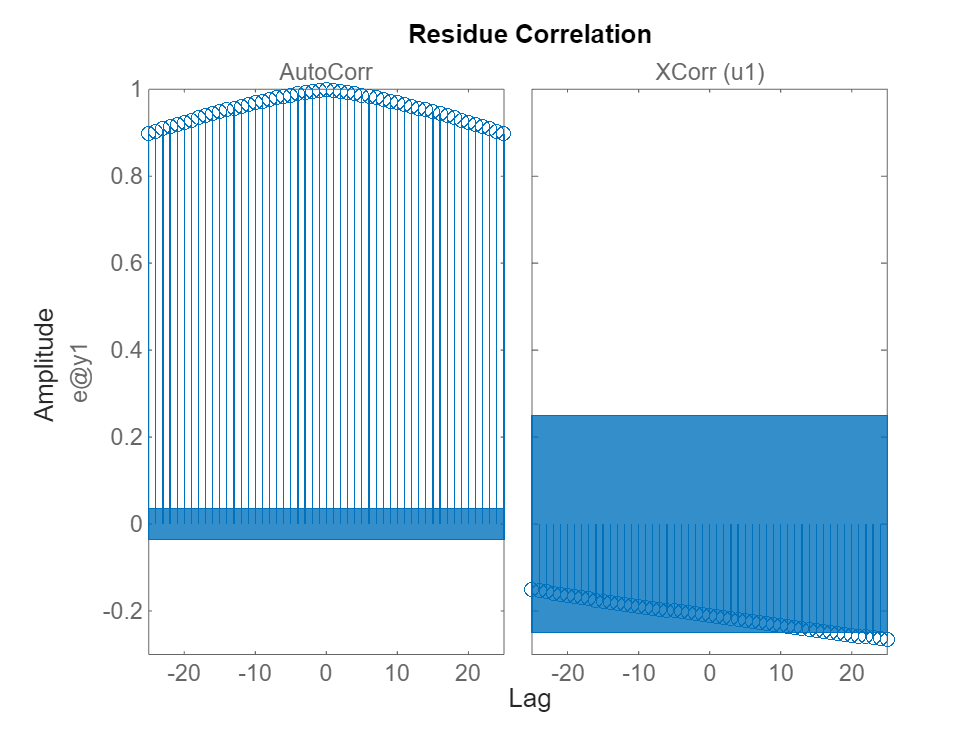

resid(sysTF_initialized,data);

### **Process Model Estimation**

sysP1D  = procest(data,'P1D')

sysP1D =
 
Process model with transfer function:
             Kp                      
  G(s) = ---------- * exp(-Td*s)     
          1+Tp1*s                    
                                     
        Kp = 0.90548                 
       Tp1 = 0.32796                 
        Td = 0.25943                 
                                     
Parameterization:
    {'P1D'}
   Number of free coefficients: 3
   Use "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using PROCEST on time domain data "data".
Fit to estimation data: 70.4%                      
FPE: 0.005614, MSE: 0.005607                       
 
Model Properties


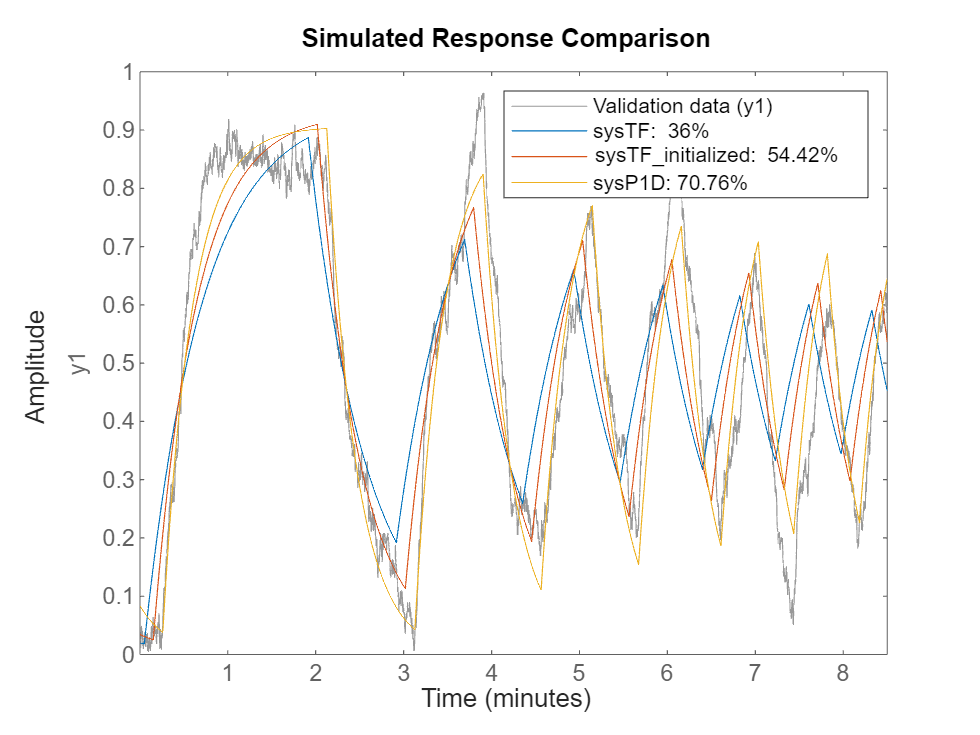

compare(data,sysTF,sysTF_initialized, sysP1D)

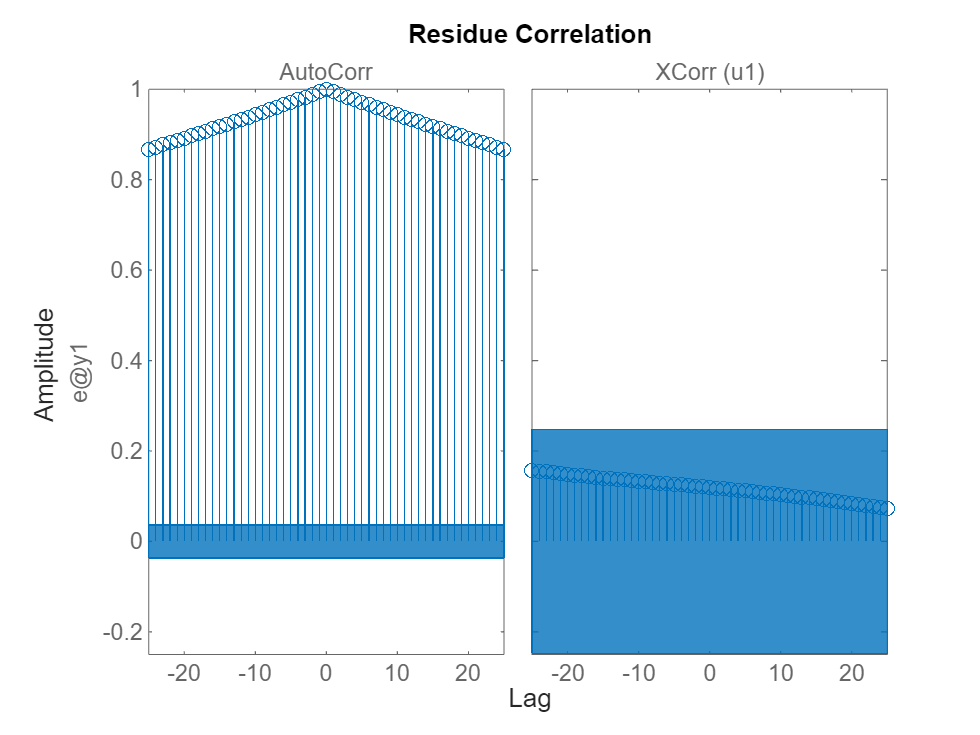

resid(sysP1D,data);

### **Process Model Estimation with Disturbance Model**

sysInit = idproc('P1D','TimeUnit','minutes');
sysInit.Structure.Kp.Value    = 1;
sysInit.Structure.Kp.Minimum  = 0;
sysInit.Structure.Tp1.Value   = 1;
sysInit.Structure.Tp1.Maximum = 10;
sysInit.Structure.Td.Value    = 0.2;
sysInit.Structure.Td.Minimum  = 0;
sysInit.Structure.Td.Maximum  = 1;

% specify ARMA1 disturbance model
opt = procestOptions('DisturbanceModel','ARMA1');
sysP1D_noise = procest(data,sysInit,opt)

sysP1D_noise =
 
Process model with transfer function:                
             Kp                                      
  G(s) = ---------- * exp(-Td*s)                     
          1+Tp1*s                                    
                                                     
        Kp = 0.90893                                 
       Tp1 = 0.34418                                 
        Td = 0.2533                                  
                                                     
An additive ARMA disturbance model has been estimated
      y = G u + (C/D)e                               
                                                     
      C(s) = s + 579.9                               
      D(s) = s + 3.125                               
                                                     
Parameterization:
    {'P1D'}
   Number of free coefficients: 5
   Use "getpvec", "getcov" for parameters and their uncertainties.

Status:                                  

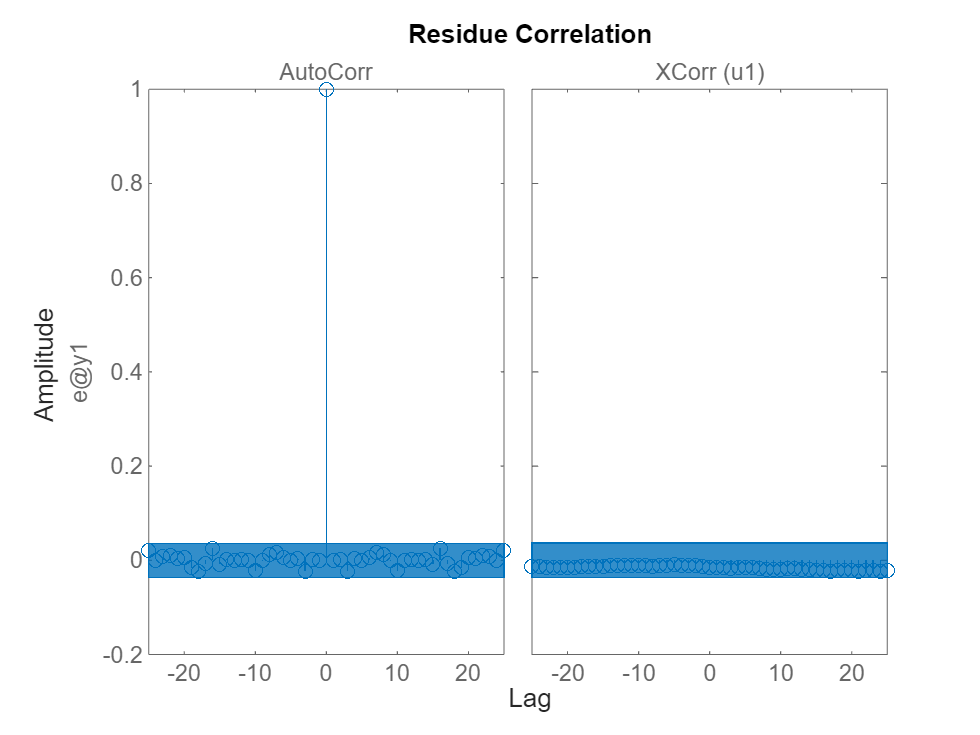


resid(sysP1D_noise,data);

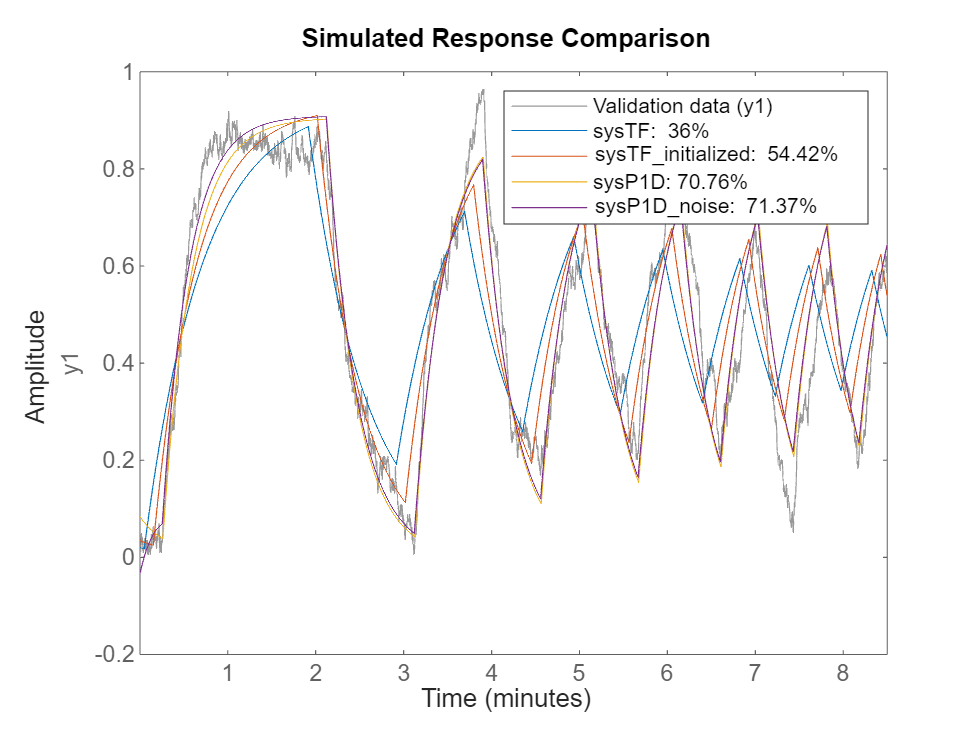

compare(data,sysTF,sysTF_initialized,sysP1D,sysP1D_noise)